# Day 6 - Initial Data Visualizations

[lr_accel, lr_gyro] = parsePowerSenseData_1('12inchtest_90bpm.csv');

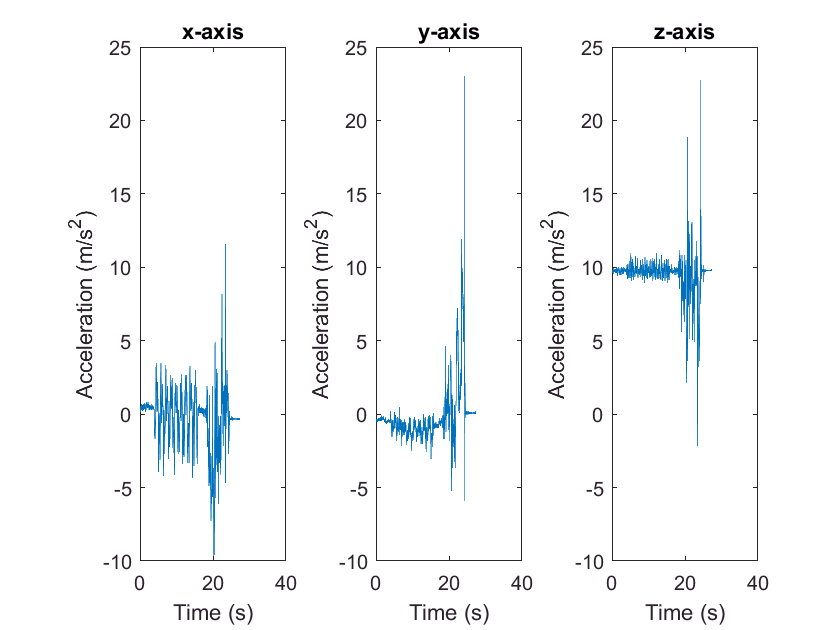

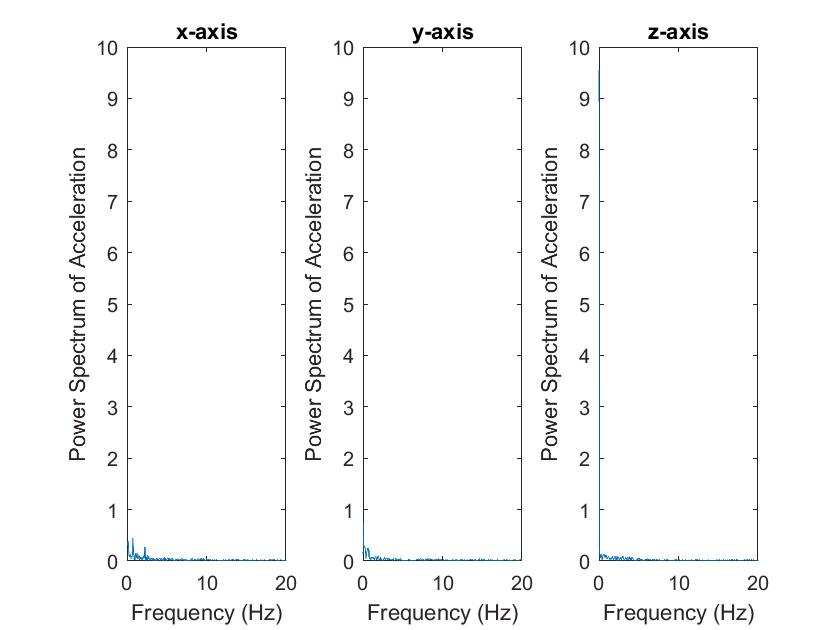

makeAccelerometerPlots(lr_accel,[],true)

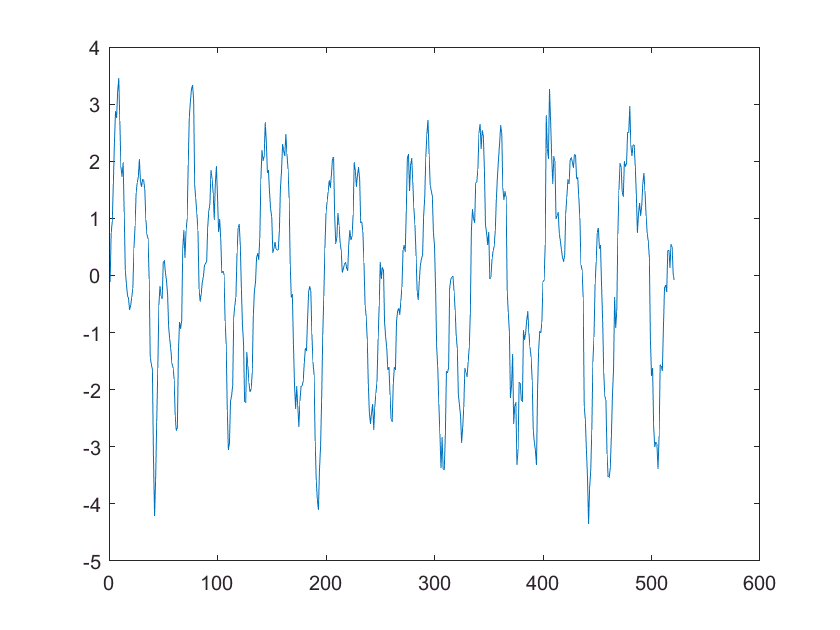

% startcut = 280;
% endcut = 800;
% 
% x_accel_orig = lr_accel(:,2);
% x_accel = x_accel_orig(startcut:endcut);
% plot(x_accel)

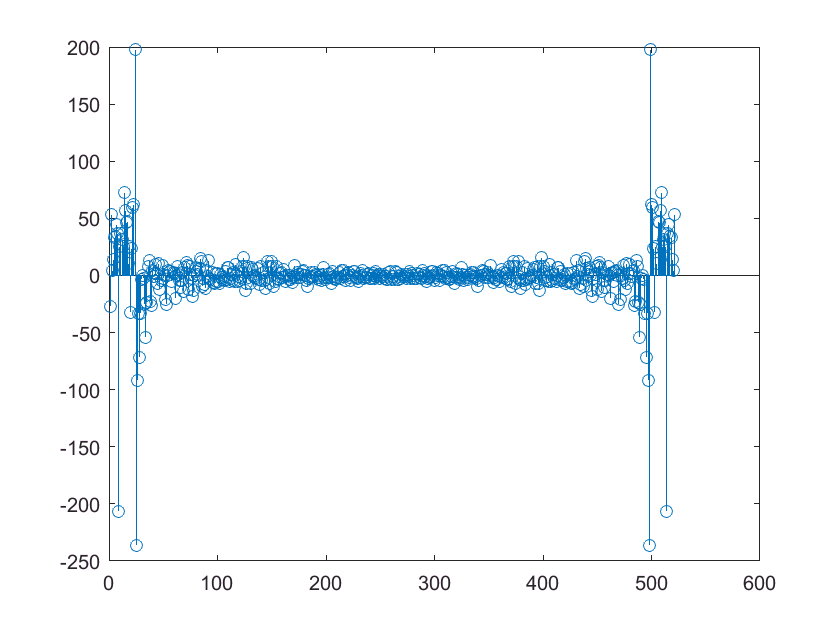

% fft_x = real(fft(x_accel));
% stem(real(fft_x))

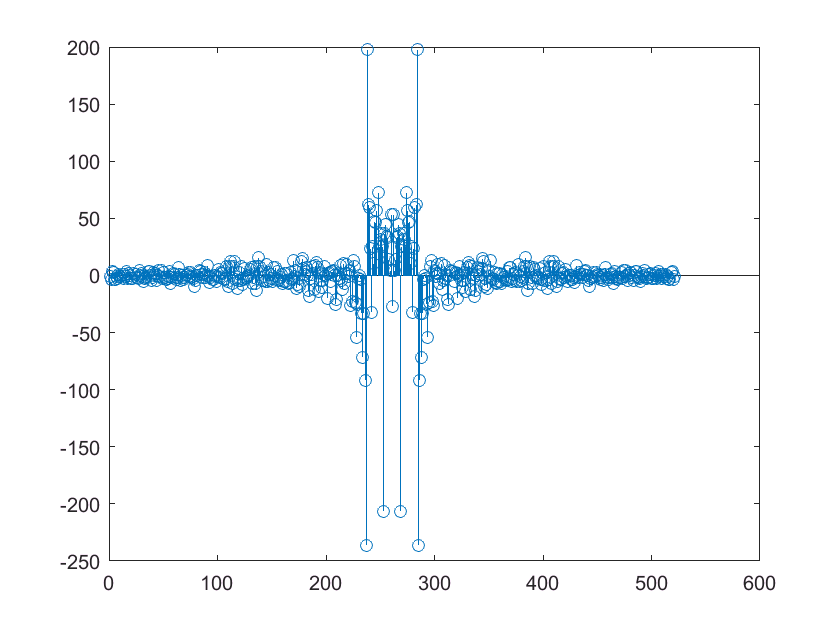

% fft_xshift = fftshift(fft_x);
% 
% [~, i] = max(fft_xshift);
% stem(fft_xshift)

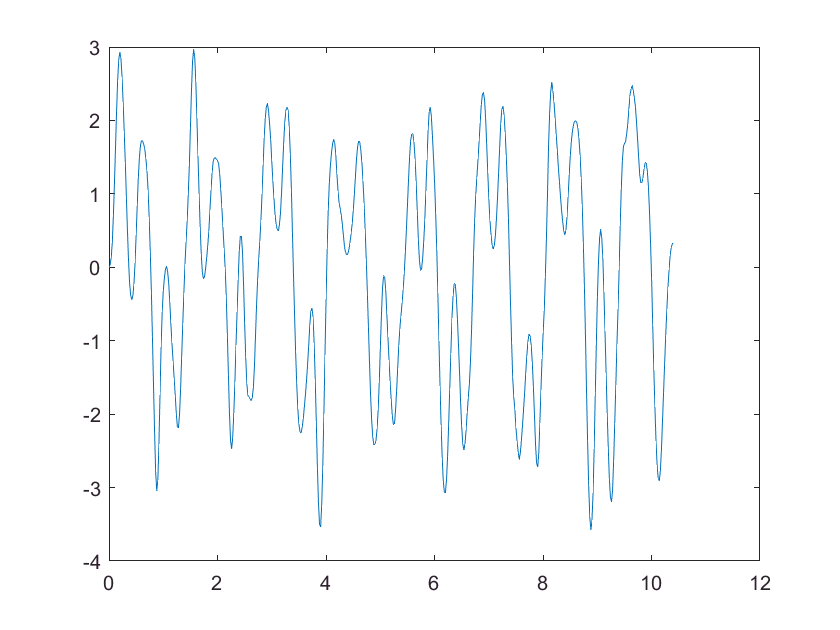

% Fs = 1/(lr_accel(20,1)-(lr_accel(19,1)));
% 
% % make_freq_plot(x_accel, Fs)
% % 
% % 
% h = [1/4 1/4 1/4 1/4];          % moving average shape
% x_accel = conv(x_accel, h);     % moving average convolution
% x_accel = x_accel(1:(end-length(h)+1)); % adjusting for conv
% x_accel = conv(x_accel,h);      % move the average again
% x_accel = x_accel(1:(end-length(h)+1)); % adjusting for conv
% x_times = lr_accel(:,1);        % grab times column
% x_times = x_times(startcut:endcut);     % cutoff bad data
% x_times = x_times-x_times(1);   % center unex times
% 
% plot(x_times, x_accel)

% fft_clean = fft(x_accel)

fft_clean =    1.0e+02 *

  -0.2754 + 0.0000i
   0.5269 - 0.1537i
   0.0354 - 0.0560i
   0.1457 + 0.0895i
   0.3380 + 0.0838i
   0.3159 - 0.1358i
   0.5298 + 0.3669i
   0.5253 + 0.6125i
  -2.9891 - 2.8589i
   0.0239 - 0.6898i
   0.1989 - 0.4756i
   0.0495 - 0.6578i
   0.1765 - 0.1979i
   0.5943 - 0.3683i
   0.5277 - 0.1650i
   0.4376 - 0.1315i
   0.3199 - 0.3327i
   0.1204 + 0.0110i
   0.3943 + 0.1282i
  -0.2923 + 0.1338i
   0.2279 - 0.0724i
   0.0511 - 0.7404i
  -0.1142 - 0.8996i
   0.7750 - 1.7165i
  -0.9554 + 1.9784i
  -0.3153 + 0.7990i
  -0.1041 + 0.2900i
  -0.6905 + 0.2996i
   0.0542 + 0.3743i
  -0.1545 - 0.0526i
   0.0702 + 0.0369i
   0.4386 + 0.2408i
  -0.3414 + 0.0798i
  -0.0023 + 0.4787i
  -0.3659 + 0.0757i
  -0.2167 - 0.1283i
  -0.2081 - 0.1638i
  -0.2278 + 0.1293i
  -0.0120 + 0.2023i
   0.4292 + 0.0372i
  -0.1183 - 0.0053i
   0.0989 - 0.0021i
  -0.0391 - 0.0699i
   0.1289 - 0.0085i
   0.1185 + 0.0478i
  -0.0309 - 0.0686i
  -0.0433 + 0.0872i
   0.0181 + 0.0282i
  -0.1118 - 0.

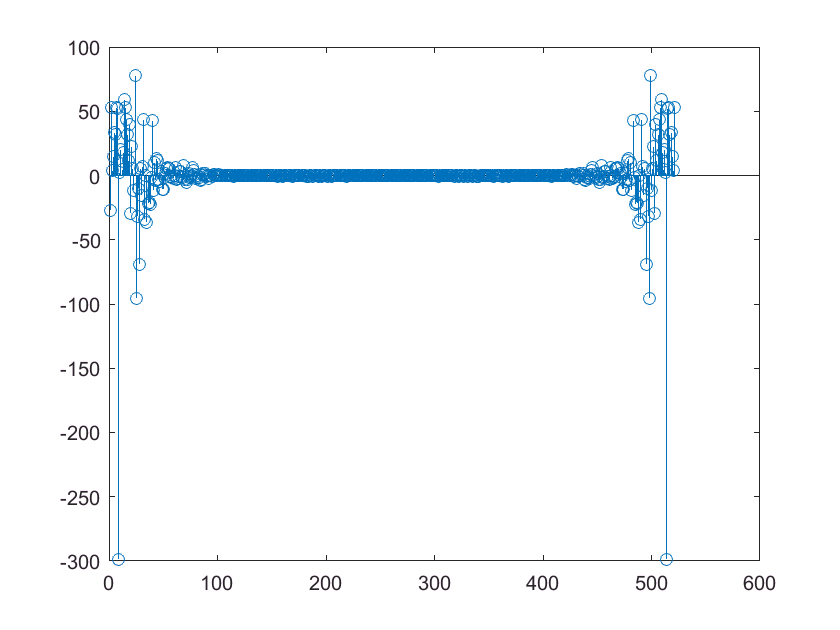

% stem(real(fft_clean))

% % 
% % period1 = 34:71;
% % xacc_int = x_accel(period1);
% % xtime_int = x_times(period1);
% % 
% % velocity = cumtrapz(xtime_int, xacc_int);
% % position = cumtrapz(xtime_int, velocity);
% % 
% % figure
% % plot(xtime_int, xacc_int)
% % plot(xtime_int, velocity)
% % plot(xtime_int, position) 
% % plot(x_times, x_accel)